clear
close all

T = 0.01;
z = tf([1 0],[1],T);

a = 1;
b = 1;

G = b / (z - a)

G =
 
    1
  -----
  z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.




b0 = 0.4673;
b1 = -0.3393;
a1 = -1.5327;
a2 = 0.6607;

Td = (b0*z + b1) / (z^2 + a1*z + a2)

Td =
 
    0.4673 z - 0.3393
  ----------------------
  z^2 - 1.533 z + 0.6607
 
Sample time: 0.01 seconds
Discrete-time transfer function.




kp = -b1 / b;
ki = (b0 + b1) / b;

C = kp + ki*z / (z -1)

C =
 
  0.4673 z - 0.3393
  -----------------
        z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



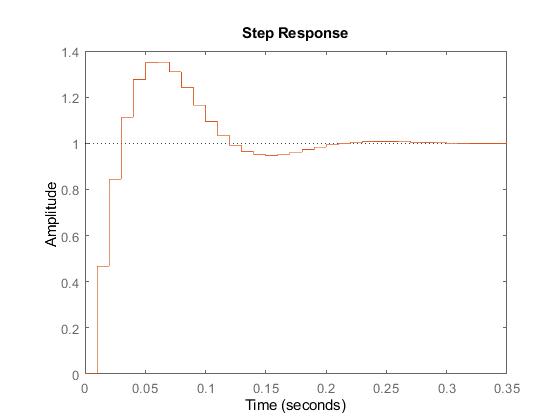

step(Td)
hold on
step(C*G / (1 + C*G))
hold off

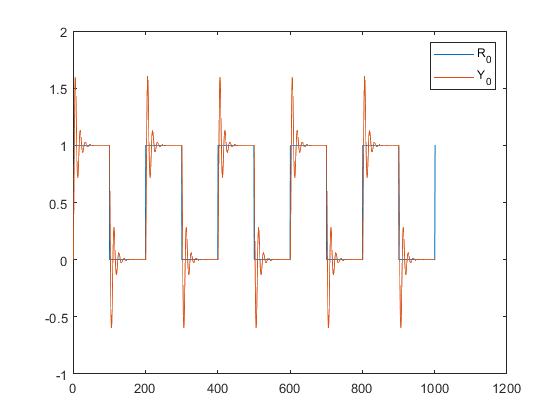


i = 1;
kp0 = 0.2;
ki0 = 0.2;
out = sim("simulacao.slx");
ro0 = [kp0, ki0];
y0 = out.y.data';
u0 = out.u.data';
r0 = out.r.data';
lambda = 10^(-3);
delta = 0.000001;

[ro] = frit(ro0,y0,u0,lambda,delta);

plot(r0)
hold on
plot(y0)
legend("R_0","Y_0")
hold off

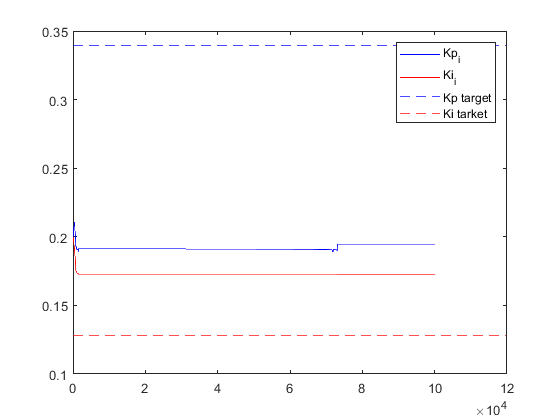


plot(ro(1,:),"b")
hold on
plot(ro(2,:),"r")
yline(kp,"b--")
yline(ki,"r--")
legend("Kp_i","Ki_i","Kp target","Ki tarket")
hold off

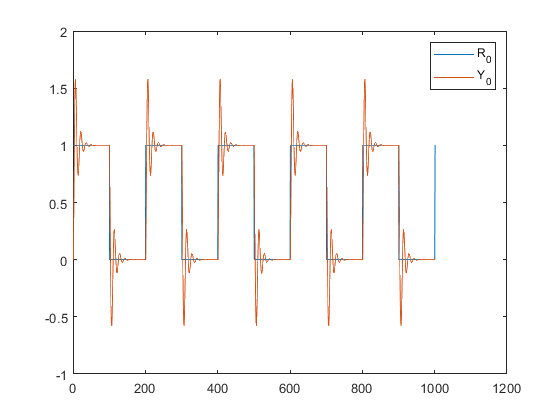



kp0 = ro(1,end);
ki0 = ro(2,end);

out = sim("simulacao.slx");
ro0 = [kp0, ki0];
y0 = out.y.data';
u0 = out.u.data';
r0 = out.r.data';
lambda = 10^(-3);
delta = 0.000001;

[ro] = frit(ro0,y0,u0,lambda,delta);

plot(r0)
hold on
plot(y0)
legend("R_0","Y_0")
hold off

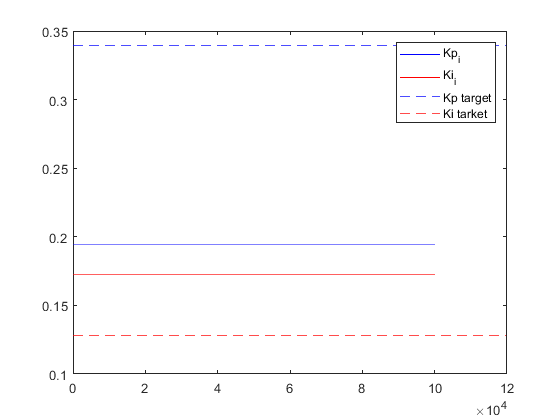


plot(ro(1,:),"b")
hold on
plot(ro(2,:),"r")
yline(kp,"b--")
yline(ki,"r--")
legend("Kp_i","Ki_i","Kp target","Ki tarket")
hold off